## **User Inputs:**

clc; 
close all; 
clear;
A = input('Enter the Amplitude of the carrier Wave: ');
Fc = 30000;     % hertz 
Fs = 100000;    % hertz 
x = input('Enter the recording Time: ');   %SECONDS
Order = 2;
dt = 1/Fs;                               % seconds per sample
StopTime = x;            
t = (0:dt:StopTime-dt)'; 
N=size(t,1);

## Carrier Wave

Carrier = (A*cos(2*pi*Fc*t)');

## Signal Wave = Recorded Voice signal

recObj = audiorecorder(Fs,16,1);         
disp('Start speaking.')

Start speaking.


recordblocking(recObj, x);
disp('End of Recording.');

End of Recording.


Input_Signal=(getaudiodata(recObj))';

## Filtering out the Input Signal to desired Frequency

beginFreq = 1000 / (Fs/2);
endFreq = 4000 / (Fs/2);
[b,a] = butter(Order, [beginFreq, endFreq], 'bandpass');

## Bandpass filter design

Signal = filter(b, a, Input_Signal);

## Signal Modulation Large Carrier

Modulated_lc = (A + Signal).* (Carrier);

## Signal Modulation Double Side Band Supressed Carrier

Modulated = Signal.*Carrier;

## Designing Of Bandpass filter for Demodulation

Freq1 = 20 / (Fs/2);
Freq2 = Fc / (Fs/2);
[num,den] = butter(Order,[Freq1,Freq2],'bandpass');

## Demodulation of Signal (Double Side Band Supressed Carrier) 

Demodulated = filter(num,den,Modulated);
Demodulated1 = 2* Demodulated.*Carrier;
[e,f] = butter(Order*2,(Fc/2)/Fs,'low');
Demodulated2 = filter(e,f,Demodulated1);


## Demodulation of Signal (Large Carrier)

en = lowpass(envelope(Modulated_lc), 0.2, dt);

## Plotting Of Carrier Wave

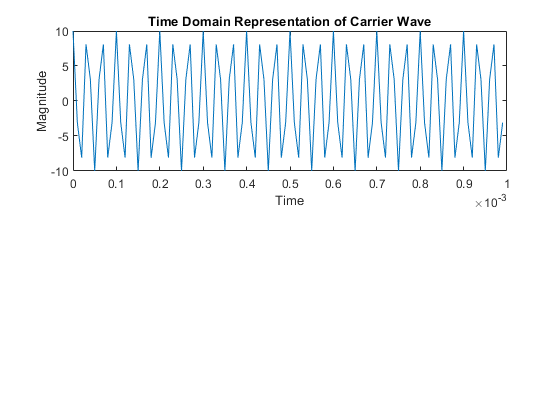

figure ('Name',' Graph Plot of Carrier and Message signal')
subplot(211)                                              
plot(t(1:100),Carrier(1:100));
title('Time Domain Representation of Carrier Wave');  
xlabel('Time');
ylabel('Magnitude');

## Plotting Of Signal

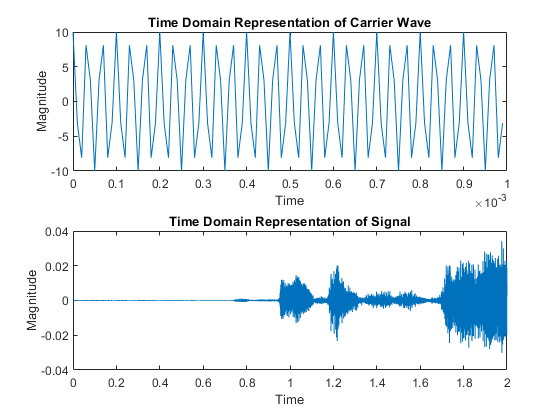

subplot(212) 
plot(t,Signal);
title('Time Domain Representation of Signal');  
xlabel('Time');
ylabel('Magnitude');

## Plotting Of Modulated Signal

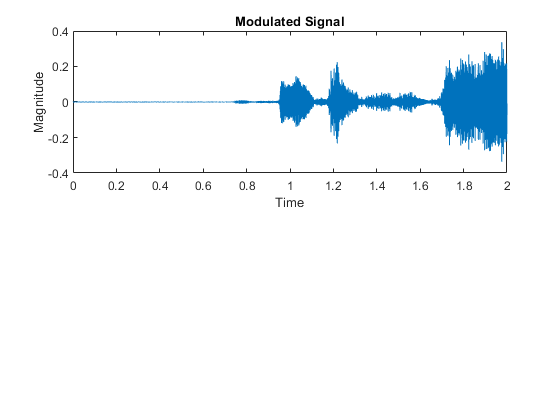

figure ('Name',' Graph Plot of Modulated and Demodulated Signal (AM-DSBSC)')
subplot(211)       
plot(t,Modulated)
title('Modulated Signal');  
xlabel('Time');
ylabel('Magnitude');

## Plotting Of Demodulated Signal

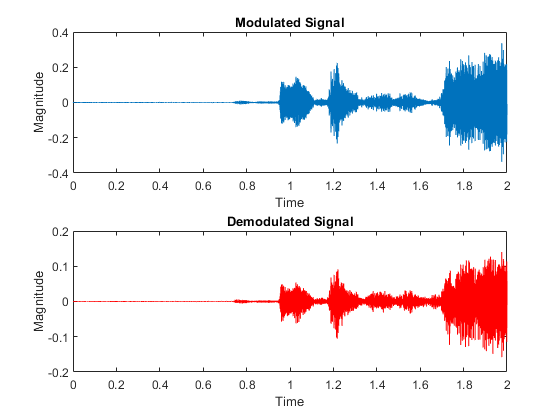

subplot(212) 
plot(t,Demodulated2,'r')
title('Demodulated Signal');  
xlabel('Time');
ylabel('Magnitude');

## Plotting Of Modulated Signal - LC

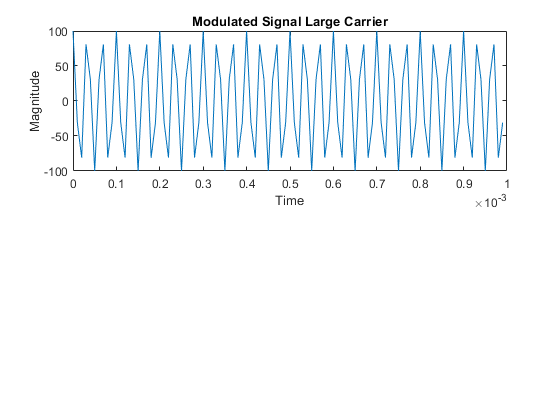

figure ('Name','Graph Plot of Modulated and Demodulated Signal (AM-LC)')
subplot(211)       
plot(t(1:100),Modulated_lc(1:100))
title('Modulated Signal Large Carrier');  
xlabel('Time');
ylabel('Magnitude');

## Plotting Of Demodulated Signal - Envelope

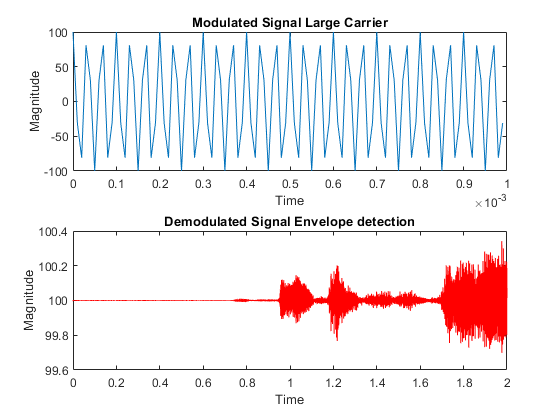

subplot(212) 
plot(t,en,'r')
title('Demodulated Signal Envelope detection');
xlabel('Time');
ylabel('Magnitude');

## Frequency Domain Analysis

fCarrier = (fftshift(fft(Carrier)));
fSignal = (fftshift(fft(Signal)));
fMod = (fftshift(fft(Modulated)));
fDemod = (fftshift(fft(Demodulated2)));
fMod_lc = (fftshift(fft(Modulated_lc)));
fDemod_lc = (fftshift(fft(en)));
freq = -Fs/2:(Fs/N):(Fs/2)-(Fs/N);

## Ploting Of Frequencies of the Carrier and Message Signal

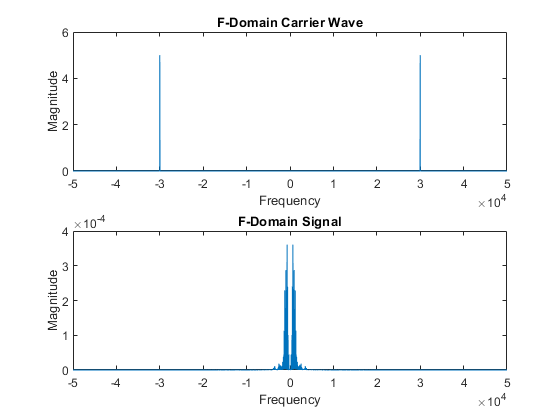

figure ('Name','Graph Plot of Frequency Domain Carrier and Message Signal')
subplot(211)
plot(freq,abs(fCarrier)/N);
title('F-Domain Carrier Wave');  
xlabel('Frequency');
ylabel('Magnitude');
subplot(212)
plot(freq,abs(fSignal)/N);
title('F-Domain Signal');  
xlabel('Frequency');
ylabel('Magnitude');

## Ploting Of Frequencies of the Double SIde Band Supressed Carrier Modulation and Demodulation

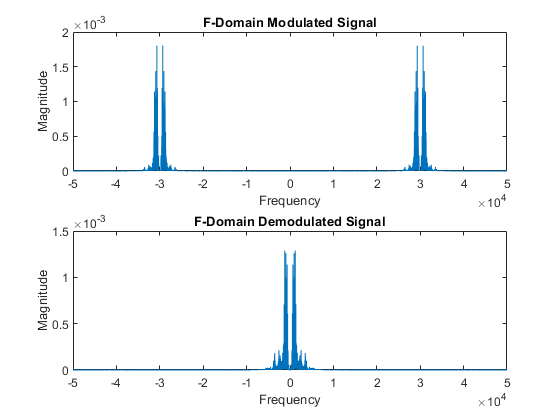

figure ('Name','Graph Plot of Frequency Domain Modulation and Demodulation (AM-DSBSC)')
subplot(211)
plot(freq,abs(fMod)/N)
title('F-Domain Modulated Signal');  
xlabel('Frequency');
ylabel('Magnitude');
subplot(212)
plot(freq,abs(fDemod)/N);
title('F-Domain Demodulated Signal');  
xlabel('Frequency');
ylabel('Magnitude');

## Ploting Of Frequencies of the Large Carrier Modulation and Demodulation

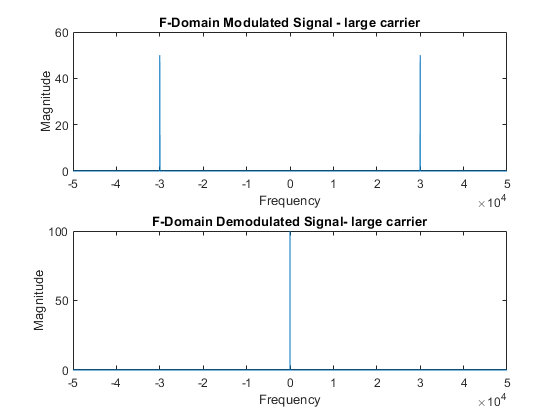

figure ('Name','Graph Plot of Frequency Domain Modulation and Demodulation (AM-LC)')
subplot(211)
plot(freq,abs(fMod_lc)/N)
title('F-Domain Modulated Signal - large carrier');  
xlabel('Frequency');
ylabel('Magnitude');
subplot(212)
plot(freq,abs(fDemod_lc)/N);
title('F-Domain Demodulated Signal- large carrier');  
xlabel('Frequency');
ylabel('Magnitude');

## Verifying the output

disp('The original Signal.');

The original Signal.


sound(Signal,Fs,8);
pause(x);
disp('The Demodulated Signal.');

The Demodulated Signal.


sound(Demodulated2,Fs,8)